# Examen 1 comunicaciones

## **Generacion componentes para Señal DBLPS**

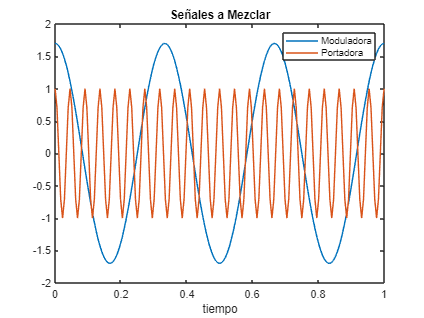

%Freq Muestreo
%Parametros
kps_64      =                 176;      %Muestreo Nyquist 4 veces la freq de la portadora
time        =        0:1/kps_64:1;      %Tiempo de Muestreo
time_am     =        -10:1/120:10;      %Rango dinamicco -10s to 10s
%señal Portadora
ap          =                1;        %Amplitud portadora
freq_port   =               22;        %Frecuencia de Portadora
wp          =   2*pi*freq_port;
port_sig    =  ap*cos(wp*time);
%señal moduladora
am          =             1.7;          %Amplitud Moduladora
freq_mod    =               3;          %Frecuencia de Moduladora
wm          =   2*pi*freq_mod;
mod_sig     =   am*cos(wm*time);        %Señal Modulada
% Señales en tiempo
figure(1);
plot(time, mod_sig)
hold on
plot(time, port_sig)
title('Señales a Mezclar');
xlabel('tiempo')
legend({'Moduladora','Portadora'},'Location','northeast')
hold off

## Modulacion AM Doble Banda Lateral con Portadora Suprimida (DBLPS)

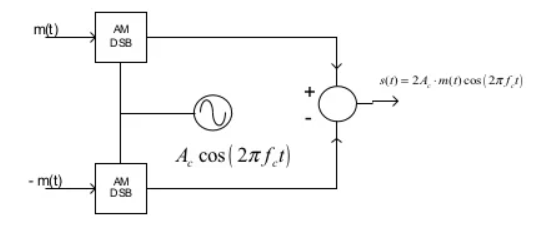

Primero necesitamos desfazar la señal moduladora 180° para tenerla invertida, entonces la multiplicamos un la portadora y al final sumamos las diferencias de las señales para tener la señal deseada

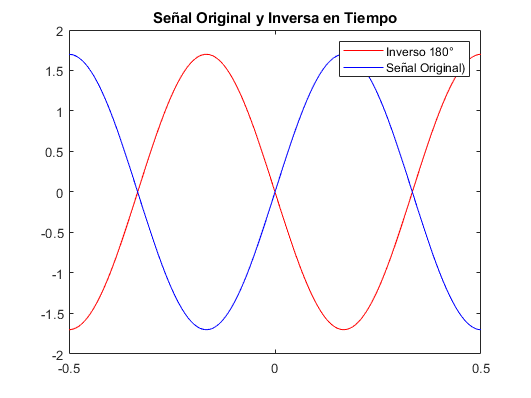

time_dsb    =       -.5:1/kps_64:.5;  %Tiempo de Muestreo
%   Inversion de Moduladora 180°
wm          =   (pi).*freq_mod;     
mod_sig_180 =   am.*-cos(wm*time);                   
mod_sig_0 =   am.*cos((wm)*time);
figure(4)
plot(time_dsb,mod_sig_180,'r',time_dsb,mod_sig_0,'b'); 
legend('Inverso 180°','Señal Original)');
title('Señal Original y Inversa en Tiempo');

## Modulador Balanceado 1 y 2

mod_bal_01 =    mod_sig_0 .* port_sig;
%Modulador Balanceado 2
mod_bal_02 =  mod_sig_180 .* port_sig;


## Diferencia de Señales

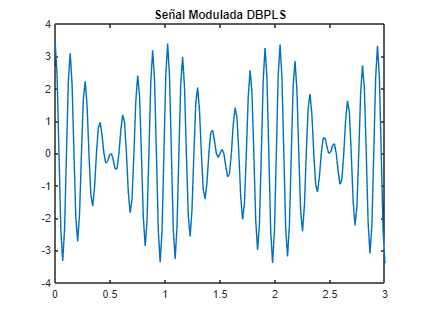

sig_am_dsbsc = mod_bal_01 - mod_bal_02;
plot(time*3,sig_am_dsbsc); 
title('Señal Modulada DBPLS');

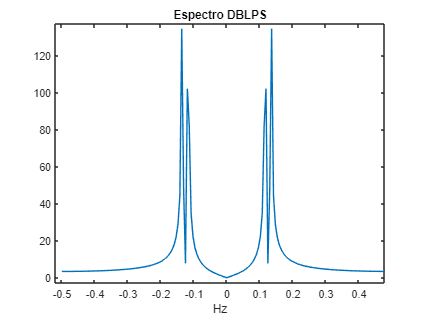

figure(8)
plot(time_dsb,abs(ttof(sig_am_dsbsc)));
title('Espectro DBLPS');
%xticklabels({'-120','0','\120'})
xlabel('Hz')